clc, clear;
format long;

% 2. plot and subplot
theta = (-2*pi):0.01:(2*pi);
y1 = 1 + 2 .* cos(theta);
y2 = 1 + 2 .* cos(theta) + 2 .* cos(2 .* theta);
y3 = 1 + 2 .* cos(theta) + 2 .* cos(2 .* theta) + 2 .* cos(3 .* theta);

figure;
plot(theta, y1, "Color","red","LineStyle","-");
xlim([-2*pi, 2*pi]);
ylim([-2, 7]);
hold on;
plot(theta, y2, "Color","blue", "LineStyle","--");
plot(theta, y3, "Color",'black',"LineStyle",'-.');
hold off;

figure;
subplot(1, 3, 1);
plot(theta, y1, "Color","red","LineStyle","-");
subplot(1, 3, 2);
plot(theta, y2, "Color","blue", "LineStyle","--");
subplot(1, 3, 3);
plot(theta, y3, "Color",'black',"LineStyle",'-.');

clc, clear;
format long;

% 3. equation
% step-1 identify the rage
figure;
x = 0:0.01:10;
y = f1(x);
plot(x, y);
hold on;
plot(x, zeros(size(x)));
% 6 roots, ranges of two smallest roots: [2,3], [4,5]

% step-2 solve the equation
func0 = @(t) cos(exp(3 ./ (t+1))) .* sin(2 .* t)
func = @(x) integral(func0, 0, x) - 0.54;
fsolve(func, 2) % 2.4648348
fsolve(func, 4) % 4.3164310
% disp("2 smallest roots:", r1,r2)

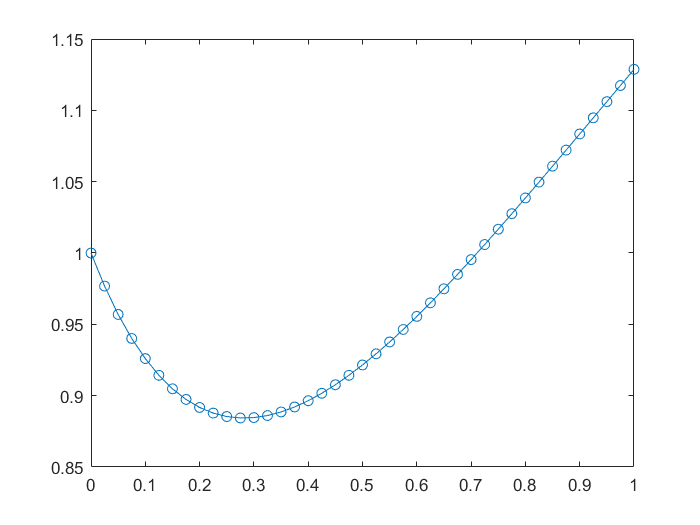

clc, clear;
format long;

% 4. ode
[t,y] = ode45(@(t,y) -2*y^2+2*t+1, [0,1], 1);

figure;
plot(t,y,'-o');
xlim([0,1]);

function y = f1(x)
    y = zeros(1, length(x));
    fun = @(t) cos(exp(3 ./ (t+1))) .* sin(2 .* t);
    for i = 1 : length(x)
        y(i) = integral(fun, 0, x(i)) - 0.54;
    end
end